# Balanced OpAmp

## What is and why should we use them

A balanced amplifier has a single input and two outputs. Imagine that we need to drive that input signal for a long distance, electrical noise can be introduced by the environment or other electrical components and information can be processed wrongly by the final user. Therefore, we use that balanced amplifier to send two signals, one is the same as the input and the other is inverted.

Before using the signal that arrives from the balanced amplifier circuit, we pass through a differential amplifier with gain equal to one half in order to remove noise. Hence, the main application for the balanced amplifier is to help us to deal with noise withouth complex processing techniques.

## Design specification for a balanced amplifier

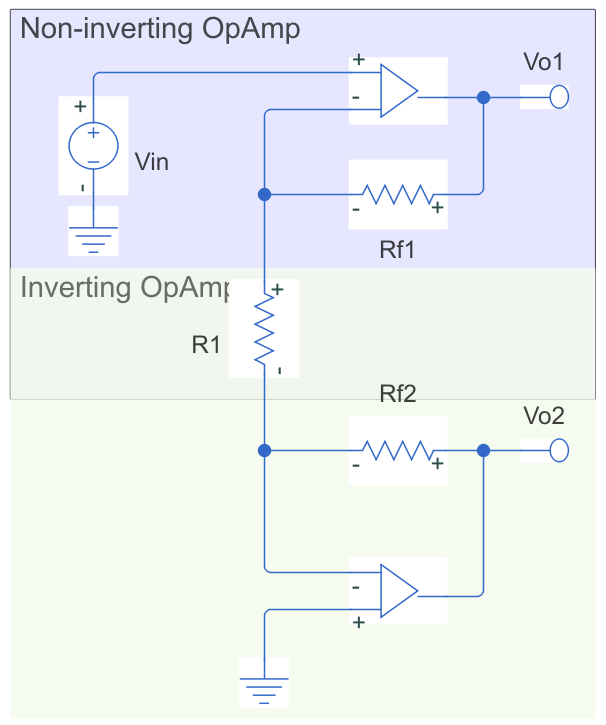

In the figure above, since we are using OpAmps, the voltage across the input terminals of the OpAmp in the green area is grounded, therefore, we can consider that the circuit in the violet area is a non-inverter amplifier and the circuit in the greend area is an inverter amplifier. 

The non-inverter amplifier has an output value of


$$V_{o1}= (1+\frac{R_{f1}}{R_1})\times{V_{in}}$$


The inverter amplifier has an output value of 


$$V_{o2}= (-\frac{R_{f2}}{R_1})\times{V_{in}}$$


We want to design such as the magnitude of the gain A of this balanced output amplifier circuit to be equal to $6$ and the maximum current through $R_{f1}$ and $R_{f2}$ to be $1mA$. When the magnitude of $V_{o1}$ is equal to the magnitude of $V_{o2}$, is equal to $12V$.

## Design analysis

From the last two equations we can impose the gain condition. We can choose $R_{f1}$, $R_{f2}$, and $R_1$. So that the gain is equal to 6 in the non-inverter and negative 6 in the non-inverter amplifier circuit. But to implement the second condition we need another equation. An equation for the current through $R_{f1}$ and $R_{f2}$ in terms of the circuit component values. 

Now, remember there's no current into the input terminals of an op amp because of infinite input impedance. So the current into the inverting terminal is zero in both opamps. So any current that flows through $R_{f1}$ must also flow through $R_1$ and flow through $R_{f2}$. So I can use Ohm's law to calculate that current. The difference in voltage across this series combination of three resistors must be equal to the current through the resistors times the resistance. Or in other words, I can write that $V_{o1}$ minus $V_{o2}$, the total voltage across the three resistors divided by the sum of the three resistors. The series resistors are $R_{f1}$ plus $R_{f2}$ plus $R_1$ must be equal to the current through the three resistors.


$$\frac{V_{o1} - V_{o2}}{R_{f1}+R_{f2}+R_1} = I$$


Inposing the second condition, that's it


$$\frac{12 - (-12)}{R_{f1} + R_{f2} + R_{1}} = 1mA$$


I = 1e-3;
Vo1 = 12;
Vo2 = -12;

Also

 $1+\frac{R_{f1}}{R_1}=6$, or $R_{f1}=5R_1$

syms R1
Rf1 = 5*R1;

$-\frac{R_{f2}}{R_1}=-6$, or $R_{f2}=6R_1$

Rf2 = 6*R1;
eq = (Vo1 - Vo2)/(Rf1+Rf2+R1) == I;
R1 = solve(eq, R1), Rf1 = 5*R1, Rf2 = 6*R1

$$R1 = 2000$$

$$Rf1 = 10000$$

$$Rf2 = 12000$$

using these two equations to eliminate $R_{f1}$ and $R_{f2}$, we have $R_1 = 2k\Omega$ and $R_{f1} = 10k\Omega$, $R_{f2} = 12k\Omega$.